# RRMC vertification

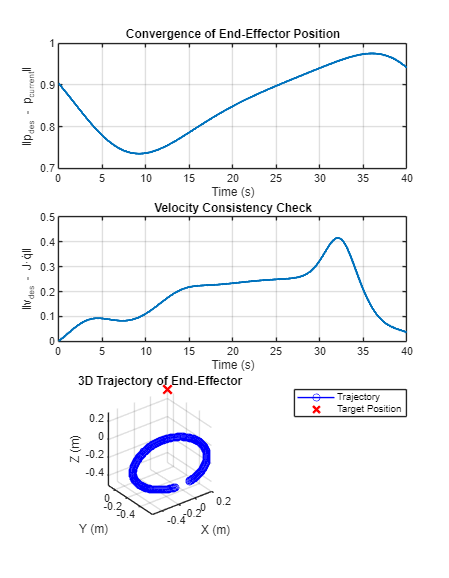

% 1. Convergence Check
% 2. Jacobian-based velocity consistency
% 3. 3D Trajectory Visualization
% - p_current (3xN)
% - v_des (6xN)
% - q_dot (6xN)
% - time vector (from any signal, e.g., q_dot.time)
% robot = loadrobot('universalUR5', 'DataFormat', 'column')
p_current_all = squeeze(out.p_current.signals.values);  % 3 x N
v_des_all = squeeze(out.v_des.signals.values);          % 6 x N
q_dot_all = squeeze(out.q_dot.signals.values);          % 6 x N
time = out.q_dot.time;                                  % 1 x N

% Desired end-effector position
p_des = [0.2; 0.1; 0.3];

%% 1. Convergence Check
% Compute position error norm over time
error_norm = vecnorm(p_des - p_current_all, 2, 1);

figure('Position', [100 100 700 900]);
subplot(3,1,1);
plot(time, error_norm, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('‖p_{des} - p_{current}‖');
title('Convergence of End-Effector Position');
grid on;

%% 2. Jacobian-based velocity consistency

robot = loadrobot('universalUR5', 'DataFormat','column');
q_example = [0; -pi/3; pi/2; 0; pi/3; 0];  % Replace with actual q 
J = geometricJacobian(robot, q_example, 'tool0');
v_est = J * q_dot_all;  % Estimate v_des

vel_error = vecnorm(v_des_all - v_est, 2, 1);

subplot(3,1,2);
plot(time, vel_error, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('‖v_{des} - J·q̇‖');
title('Velocity Consistency Check');
grid on;

%% 3. 3D Trajectory Visualization
subplot(3,1,3);
plot3(p_current_all(1,:), p_current_all(2,:), p_current_all(3,:), 'b-o');
hold on;
plot3(p_des(1), p_des(2), p_des(3), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('X (m)'); 
ylabel('Y (m)'); 
zlabel('Z (m)');
title('3D Trajectory of End-Effector');
legend('Trajectory', 'Target Position');
grid on; 
axis equal;